 %  Copyright 2021 University of Padua, Italy
 %
 %  Licensed under the Apache License, Version 2.0 (the "License");
 %  you may not use this file except in compliance with the License.
 %  You may obtain a copy of the License at
 %
 %       http://www.apache.org/licenses/LICENSE-2.0
 %
 %  Unless required by applicable law or agreed to in writing, software
 %  distributed under the License is distributed on an "AS IS" BASIS,
 %  WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied.
 %  See the License for the specific language governing permissions and
 %  limitations under the License.
 %
 % 
 % @author Nicola Ferro

# Computation of one-way ANOVA on TREC 08, 1999, AdHoc

This example shows how to compare runs from TREC 08, 1999, AdHoc using one-way ANOVA.

## Setup

Load the performance score about the runs. The file contains:

- `ap` (or another measure name): a matrix where rows are topics and columns are runs; each cell contains the AP score for a run on a given topic;

- `runs`: an array of strings containing the identifiers of the runs; elements in the array are in the same order as columns on ap;

- `topics`: an array of strings containing the identifiers of the topics; elements in the array are in the same order as rows on ap;

% Load Average Precision data
% Other measures available are: P@10, nDCG, RBP
load C:\Users\Andrea\Desktop\MAGISTRALE\Anno1-sem2\SearchEngines\HWS\seupd2021-goldr\RUN\RUN2020\RunAnalysis\runtotonlyndcg5.mat
% rename ap into measure to make follow-up processing the same for whatever
% measure we load
measure_ndcg5 = runtotonlyndcg5(1:49,:);
measure_ndcg5 = table2array(measure_ndcg5)

measure_ndcg5 =    10.0000   10.0000   10.0000   10.0000   10.0000
    0.6844    0.6844    0.6844    0.6844    0.5087
    0.5258    0.5258    0.5258    0.5920    0.4105
    0.8688    0.8539    0.8688    0.1696    0.3008
    0.6844    0.6844    0.6844         0         0
    0.5087    0.5087    0.5087    0.0848    0.1070
    0.8539    0.7227    0.8539    0.6548    0.4852
    0.4704    0.4704    0.4704         0         0
    0.8539    0.7227    0.8539    0.3601    0.1312
    0.8688    0.6548    0.8688    0.3392    0.5531



% remove the now useless ap matrix
clear runtotonlyndcg5;

% the significance level
alpha = 0.05;

Reorder the measure by mean performance

% the mean for each run across the topics
% Note that if the measure is AP (Average Precision), 
% this is exactly MAP (Mean Average Precision) for each run
m_avg_ndcg5 = mean(measure_ndcg5);

myruns_ndcg5 = ogmyruns

myruns_ndcg5 = 1×5 string array
    "run1"    "run2"    "run3"    "run4"    "run5"


% sort in descending order of mean score
[~, idx] = sort(m_avg_ndcg5, 'descend');

% re-order runs by descending mean of the measure
measure_ndcg5 = measure_ndcg5(:, idx);
myruns_ndcg5 = myruns_ndcg5(idx);

## One-way ANOVA

Compute the one-way ANOVA

% perform the ANOVA
[~, tbl_ndcg5, sts_ndcg5] = anova1(measure_ndcg5, myruns_ndcg5, 'off');

% display the ANOVA table
tbl_ndcg5

tbl_ndcg5 = 4×6 cell array
    {'Source' }    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[   42.3811]}    {[  4]}    {[ 10.5953]}    {[  1.8171]}    {[  0.1262]}
    {'Error'  }    {[1.3994e+03]}    {[240]}    {[  5.8308]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[1.4418e+03]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double}


Perform the multiple comparison

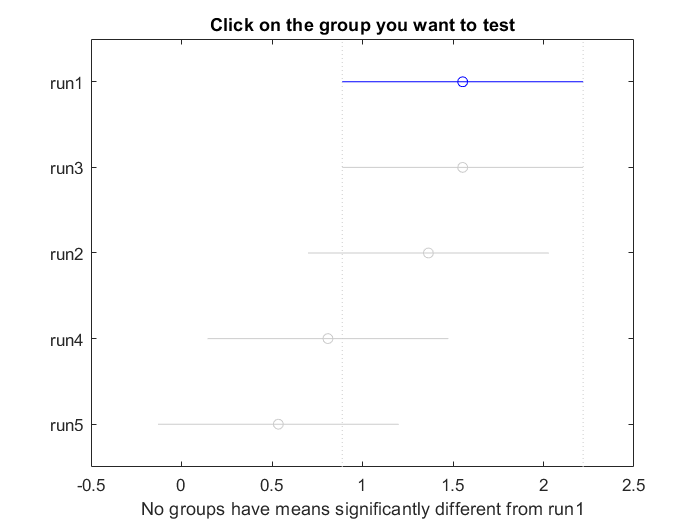

c = multcompare(sts_ndcg5, 'Alpha', alpha, 'Ctype', 'hsd'); 


% display the multiple comparisons
c

c =     1.0000    2.0000   -1.3307         0    1.3307    1.0000
    1.0000    3.0000   -1.1413    0.1894    1.5202    0.9952
    1.0000    4.0000   -0.5861    0.7446    2.0753    0.5452
    1.0000    5.0000   -0.3124    1.0183    2.3490    0.2255
    2.0000    3.0000   -1.1413    0.1894    1.5202    0.9952
    2.0000    4.0000   -0.5861    0.7446    2.0753    0.5452
    2.0000    5.0000   -0.3124    1.0183    2.3490    0.2255
    3.0000    4.0000   -0.7755    0.5552    1.8859    0.7863
    3.0000    5.0000   -0.5019    0.8289    2.1596    0.4345
    4.0000    5.0000   -1.0570    0.2737    1.6044    0.9806


## Two-way ANOVA - da finire

Compute the two-way ANOVA

% perform the ANOVA
[~, tbl2_ndcg5, sts2_ndcg5] = anova2(measure_ndcg5, 1,'off');

% display the ANOVA table
tbl2_ndcg5

tbl2_ndcg5 = 5×6 cell array
    {'Source' }    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[   42.3811]}    {[  4]}    {[ 10.5953]}    {[  5.2881]}    {[4.6232e-04]}
    {'Rows'   }    {[1.0147e+03]}    {[ 48]}    {[ 21.1393]}    {[ 10.5506]}    {[2.1293e-33]}
    {'Error'  }    {[  384.6925]}    {[192]}    {[  2.0036]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[1.4418e+03]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }



% display the ANOVA table
tbl2_ndcg5

tbl2_ndcg5 = 5×6 cell array
    {'Source' }    {'SS'        }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'    }
    {'Columns'}    {[   42.3811]}    {[  4]}    {[ 10.5953]}    {[  5.2881]}    {[4.6232e-04]}
    {'Rows'   }    {[1.0147e+03]}    {[ 48]}    {[ 21.1393]}    {[ 10.5506]}    {[2.1293e-33]}
    {'Error'  }    {[  384.6925]}    {[192]}    {[  2.0036]}    {0×0 double}    {0×0 double  }
    {'Total'  }    {[1.4418e+03]}    {[244]}    {0×0 double}    {0×0 double}    {0×0 double  }


Perform the multiple comparison

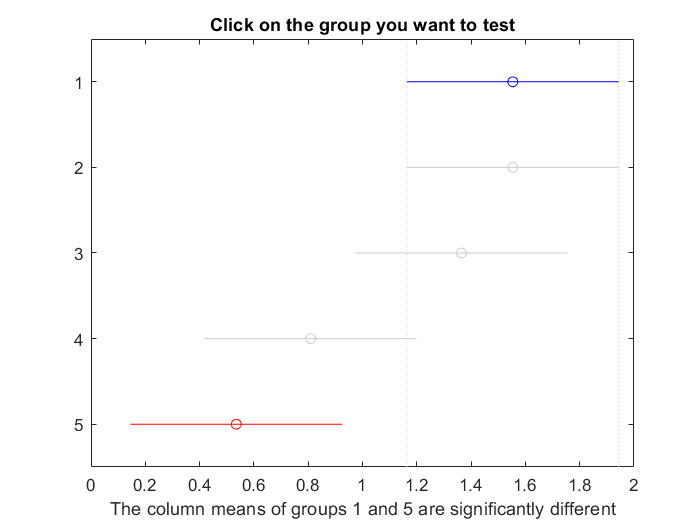

c2 = multcompare(sts2_ndcg5, 'Alpha', alpha, 'Ctype', 'hsd'); 

c2

c2 =     1.0000    2.0000   -0.7801         0    0.7801    1.0000
    1.0000    3.0000   -0.5906    0.1894    0.9695    0.9643
    1.0000    4.0000   -0.0355    0.7446    1.5247    0.0696
    1.0000    5.0000    0.2382    1.0183    1.7984    0.0034
    2.0000    3.0000   -0.5906    0.1894    0.9695    0.9643
    2.0000    4.0000   -0.0355    0.7446    1.5247    0.0696
    2.0000    5.0000    0.2382    1.0183    1.7984    0.0034
    3.0000    4.0000   -0.2249    0.5552    1.3352    0.2954
    3.0000    5.0000    0.0488    0.8289    1.6089    0.0308
    4.0000    5.0000   -0.5064    0.2737    1.0537    0.8743
